# In-class exercises - Image as a Signal

Md Mohiuddin Mollah - Digital Signal Processing 2026. One section per exercise, each followed by short answers to the Think about questions. I worked on these exercises together with a classmate.

## Exercise 1: Pixels and Quantization

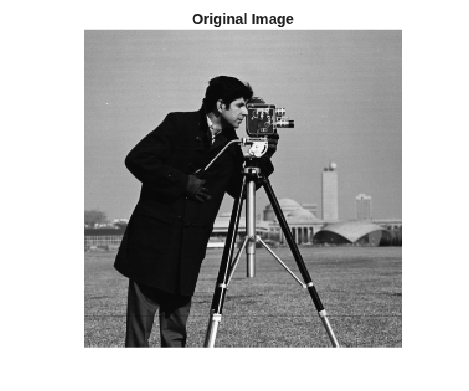

% Load image
I = imread('cameraman.tif');
rng(1);   % fixed seed, so the noise is the same on every run

% Display image
imshow(I);
title('Original Image');


% Print image information
disp('Image size:');

Image size:


disp(size(I));

   256   256




disp('Image class:');

Image class:


disp(class(I));

uint8


## Quantization

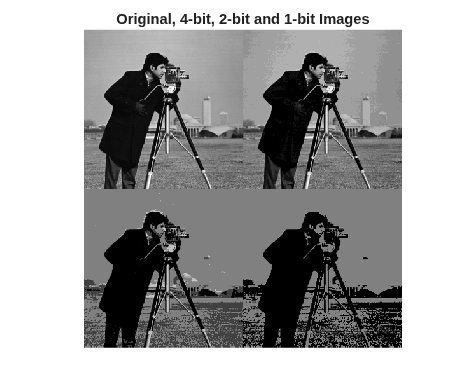

% 4-bit quantization (16 gray levels)
Q4 = uint8(floor(double(I)/16)*16);

% 2-bit quantization (4 gray levels)
Q2 = uint8(floor(double(I)/64)*64);

% 1-bit quantization (2 gray levels)
Q1 = uint8(floor(double(I)/128)*128);

% Display results
montage({I,Q4,Q2,Q1});

title('Original, 4-bit, 2-bit and 1-bit Images');

## Spatial Sampling

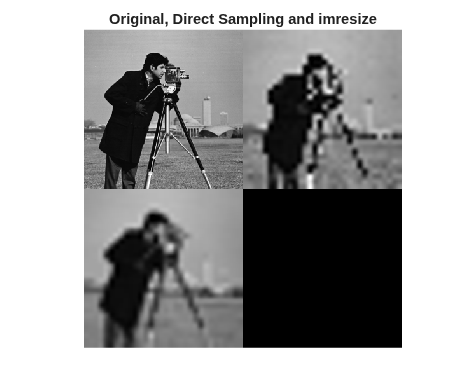

% Downsampling without imresize
A1 = I(1:8:end, 1:8:end);

% Downsampling with imresize
A2 = imresize(I, 1/8);

% Display results
montage({I,A1,A2});

title('Original, Direct Sampling and imresize');

## Exercise 1 - Short answers

The image is 256 x 256 pixels, class uint8. With 4 bits (16 grey levels) the image still looks almost normal, only the sky shows bands. With 2 bits (4 levels) there are strong false contours, but the cameraman is still easy to recognise. With 1 bit only a black and white silhouette is left, and details such as the face and the camera are gone, so this is where I stop recognising the image. Aliasing becomes visible when every 8th pixel is taken directly: thin structures such as the tripod legs become jagged and broken. imresize filters before it samples, so its result is smoother.

## Exercise 2 - Degrade an Image

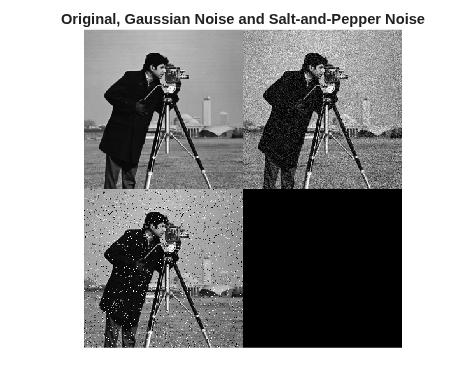

% Add Gaussian noise
Ig = imnoise(I, 'gaussian', 0, 0.01);

% Add salt-and-pepper noise
Isp = imnoise(I, 'salt & pepper', 0.05);

% Display the original and noisy images
figure;
montage({I, Ig, Isp});
title('Original, Gaussian Noise and Salt-and-Pepper Noise');

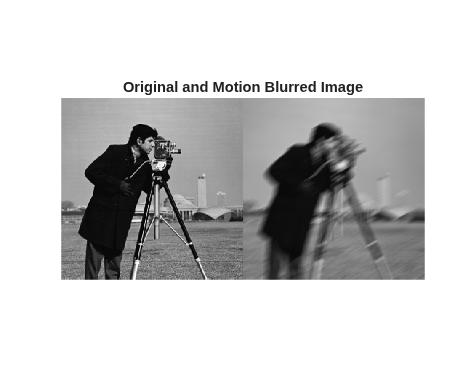


% Create a motion blur filter
hMotion = fspecial('motion', 15, 30);

% Apply motion blur
Ib = imfilter(I, hMotion, 'replicate');

% Display the result
figure;
montage({I, Ib});
title('Original and Motion Blurred Image');

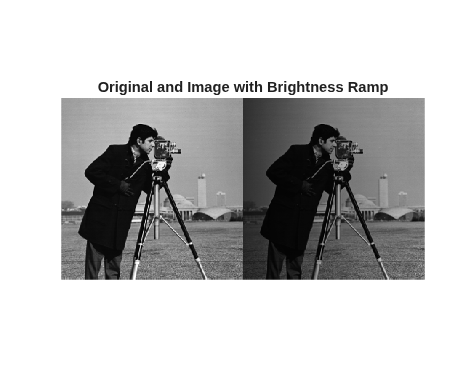


% Create a horizontal brightness ramp
[M, N] = size(I);
ramp = repmat(linspace(0.3, 1.0, N), M, 1);

% Multiply the original image by the ramp
Iramp = uint8(double(I) .* ramp);

% Display the result
figure;
montage({I, Iramp});
title('Original and Image with Brightness Ramp');

## Exercise 2 - Short answers

The Gaussian noise is additive: a random value is added to every pixel. The brightness ramp is multiplicative: every pixel is multiplied by a factor between 0.3 and 1. Motion blur is neither of them, it is a convolution with a line-shaped kernel. Salt & pepper noise replaces single pixels with black or white, and this is the noise the median filter fixes, because one extreme value never becomes the median of a 3 x 3 neighbourhood.

## Exercise 3 - Contrast and Geometry

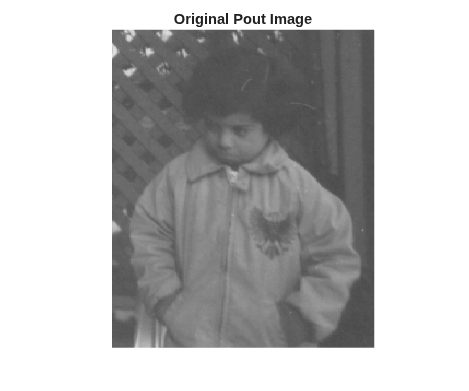

% Load the image
P = imread('pout.tif');

% Display the original image
figure;
imshow(P);
title('Original Pout Image');

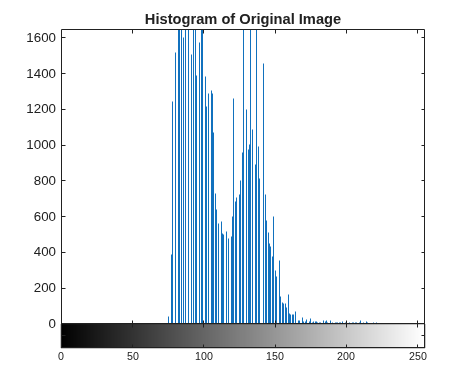


% Display the image histogram
figure;
imhist(P);
title('Histogram of Original Image');

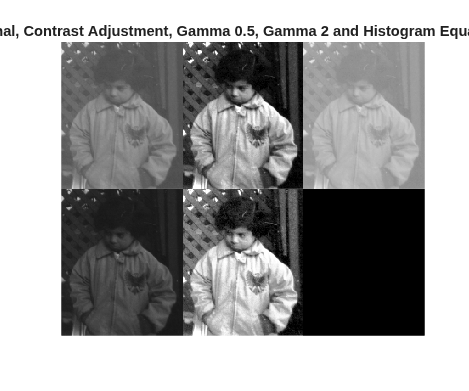


% Improve contrast automatically
P_adjust = imadjust(P);

% Gamma correction
P_g05 = imadjust(P, [], [], 0.5);
P_g2 = imadjust(P, [], [], 2);

% Histogram equalization
P_histeq = histeq(P);

% Compare all results
figure;
montage({P, P_adjust, P_g05, P_g2, P_histeq});
title('Original, Contrast Adjustment, Gamma 0.5, Gamma 2 and Histogram Equalization');

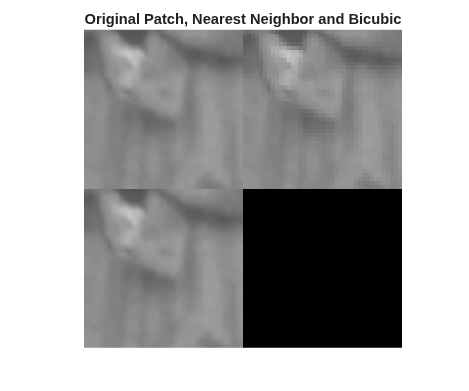


% Select a 40x40 region from the center of the image
r0 = floor(size(P,1)/2) - 19;
c0 = floor(size(P,2)/2) - 19;
patch = P(r0:r0+39, c0:c0+39);

% Enlarge the region by a factor of 8
nearest = imresize(patch, 8, 'nearest');
bicubic = imresize(patch, 8, 'bicubic');

% Display the results
figure;
montage({patch, nearest, bicubic});
title('Original Patch, Nearest Neighbor and Bicubic');

## Exercise 3 - Short answers

The histogram of pout.tif uses only the middle grey values, so the image has low contrast. histeq gives the strongest contrast and imadjust the most natural result, so I think imadjust looks best. Gamma below 1 brightens the image because the pixel values are scaled to 0...1 and raised to a power below 1, which makes every value larger, most of all the dark ones. Gamma 2 does the opposite and darkens. Nearest-neighbour interpolation only copies each pixel, so the enlarged patch is blocky. Bicubic interpolation calculates each new pixel from the 16 surrounding pixels, so edges and gradients become smooth.

## Exercise 4 - Filter and Compare

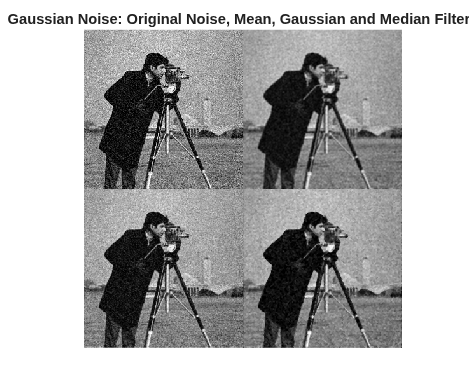

% Create mean and Gaussian filters
hMean = fspecial('average', [3 3]);
hGauss = fspecial('gaussian', [3 3], 0.5);

% Filter Gaussian-noise image
Ig_mean = imfilter(Ig, hMean, 'replicate');
Ig_gauss = imfilter(Ig, hGauss, 'replicate');
Ig_median = medfilt2(Ig, [3 3]);

% Filter salt-and-pepper image
Isp_mean = imfilter(Isp, hMean, 'replicate');
Isp_gauss = imfilter(Isp, hGauss, 'replicate');
Isp_median = medfilt2(Isp, [3 3]);

% Display results for Gaussian noise
figure;
montage({Ig, Ig_mean, Ig_gauss, Ig_median});
title('Gaussian Noise: Original Noise, Mean, Gaussian and Median Filters');

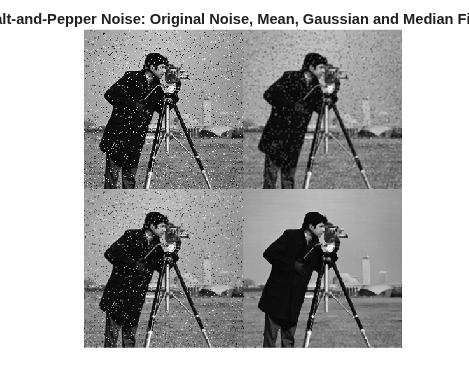


% Display results for salt-and-pepper noise
figure;
montage({Isp, Isp_mean, Isp_gauss, Isp_median});
title('Salt-and-Pepper Noise: Original Noise, Mean, Gaussian and Median Filters');


% Calculate PSNR values
noiseNames = ["Gaussian"; "Salt-and-pepper"];

MeanPSNR = [
    psnr(Ig_mean, I);
    psnr(Isp_mean, I)
    ];

GaussianPSNR = [
    psnr(Ig_gauss, I);
    psnr(Isp_gauss, I)
    ];

MedianPSNR = [
    psnr(Ig_median, I);
    psnr(Isp_median, I)
    ];

% Create and display comparison table
T = table(noiseNames, MeanPSNR, GaussianPSNR, MedianPSNR);
disp(T);

       noiseNames        MeanPSNR    GaussianPSNR    MedianPSNR
    _________________    ________    ____________    __________

    "Gaussian"            24.377        23.779         24.163  
    "Salt-and-pepper"     23.435        21.478         26.769  



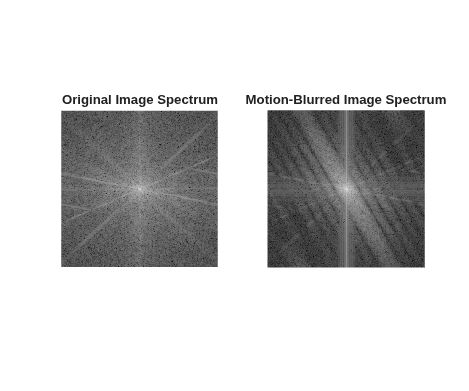


% Fourier transform of original image
F_original = fftshift(fft2(double(I)));

% Fourier transform of motion-blurred image
F_blurred = fftshift(fft2(double(Ib)));

% Calculate log magnitude spectra
S_original = log(1 + abs(F_original));
S_blurred = log(1 + abs(F_blurred));

% Display spectra
figure;
subplot(1,2,1);
imshow(S_original, []);
title('Original Image Spectrum');

subplot(1,2,2);
imshow(S_blurred, []);
title('Motion-Blurred Image Spectrum');

## Exercise 4 - Short answers

PSNR against the original: for Gaussian noise the mean filter is best (24.38 dB), then the median filter (24.16 dB) and the 3 x 3 Gaussian filter with sigma 0.5 (23.78 dB). For salt & pepper noise the median filter is clearly best (26.77 dB) against 23.44 dB for the mean and 21.48 dB for the Gaussian filter. So averaging wins for Gaussian noise and the median wins for impulse noise. In the spectrum, blurring removes high frequencies: the bright centre stays, the outer parts get darker, and motion blur adds dark stripes across the direction of the motion.

## Exercise 5 - Edge Detection

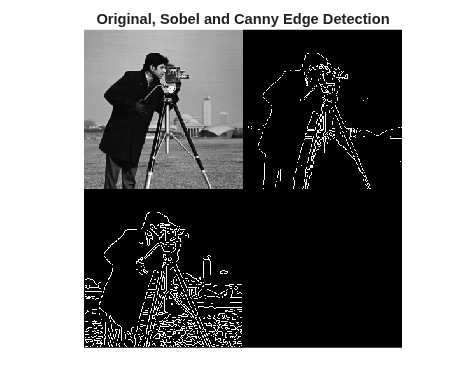

% Apply Sobel edge detection
BW_sobel = edge(I, 'sobel');

% Apply Canny edge detection
BW_canny = edge(I, 'canny');

% Display results
figure;
montage({I, BW_sobel, BW_canny});
title('Original, Sobel and Canny Edge Detection');

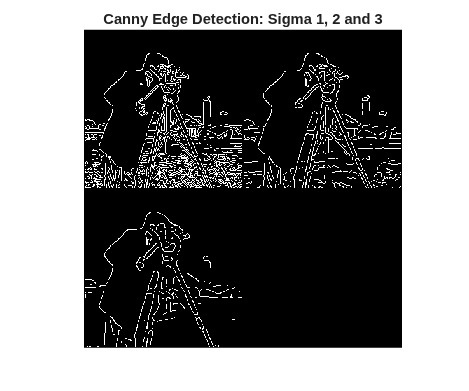


% Apply Canny with different sigma values
BW_sigma1 = edge(I, 'canny', [], 1);
BW_sigma2 = edge(I, 'canny', [], 2);
BW_sigma3 = edge(I, 'canny', [], 3);

% Display results
figure;
montage({BW_sigma1, BW_sigma2, BW_sigma3});
title('Canny Edge Detection: Sigma 1, 2 and 3');

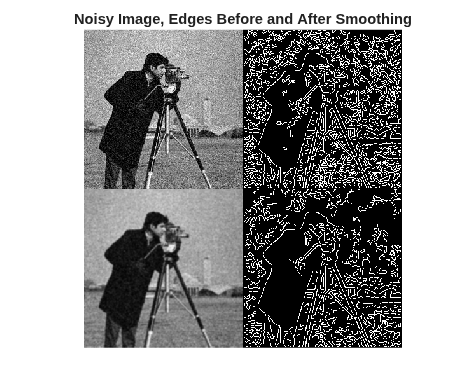


% Detect edges directly in the noisy image
BW_noisy = edge(Ig, 'canny');

% Smooth the noisy image before edge detection
Ig_smooth = imgaussfilt(Ig, 1);
BW_smooth = edge(Ig_smooth, 'canny');

% Detect edges in the clean original for comparison
BW_clean = edge(I, 'canny');

% Count edge pixels
count_noisy = nnz(BW_noisy);
count_smooth = nnz(BW_smooth);
count_clean = nnz(BW_clean);

% Count false-positive edge pixels relative to clean image
false_before = nnz(BW_noisy & ~BW_clean);
false_after = nnz(BW_smooth & ~BW_clean);

% Calculate the number of false edges removed
false_removed = false_before - false_after;

% Display results
figure;
montage({Ig, BW_noisy, Ig_smooth, BW_smooth});
title('Noisy Image, Edges Before and After Smoothing');


fprintf('Clean edge pixels: %d\n', count_clean);

Clean edge pixels: 6544


fprintf('Noisy edge pixels: %d\n', count_noisy);

Noisy edge pixels: 13610


fprintf('Smoothed edge pixels: %d\n', count_smooth);

Smoothed edge pixels: 9197


fprintf('False edges before smoothing: %d\n', false_before);

False edges before smoothing: 9372


fprintf('False edges after smoothing: %d\n', false_after);

False edges after smoothing: 5479


fprintf('False edges removed: %d\n', false_removed);

False edges removed: 3893


## Exercise 5 - Short answers

A larger sigma smooths the image more before the gradient is calculated. The edge map then has fewer edges, small details and texture such as the grass disappear, and the remaining edges are smoother and slightly rounded. Canny finds 6544 edge pixels in the clean image and 13610 in the noisy image. Smoothing first with a Gaussian filter (sigma 1) reduces this to 9197. Counted against the clean edge map, the false edge pixels drop from 9372 to 5479, so smoothing removes 3893 false edge pixels (about 42 %).

## Exercise 6 - Segment and Measure

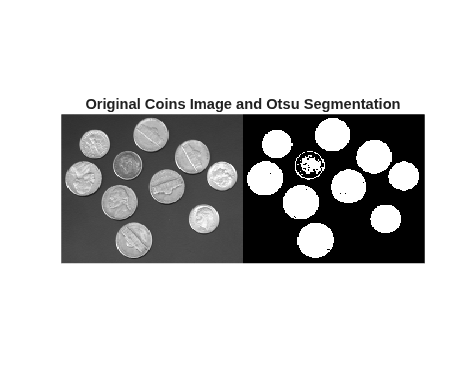

% Load the coins image
Icoins = imread('coins.png');

% Convert to grayscale if necessary
if size(Icoins, 3) == 3
    Icoins = rgb2gray(Icoins);
end

% Calculate Otsu threshold
level = graythresh(Icoins);

% Convert image to binary
BW = imbinarize(Icoins, level);

% Display original and binary images
figure;
montage({Icoins, BW});
title('Original Coins Image and Otsu Segmentation');

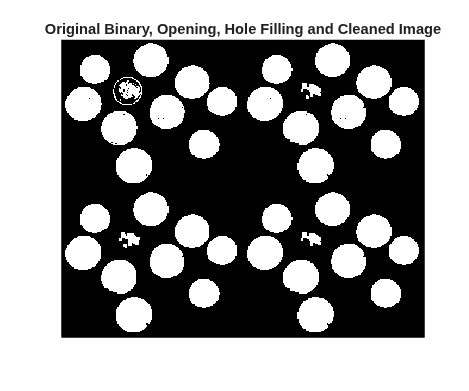


% Create a disk-shaped structuring element
se = strel('disk', 3);

% Remove small protrusions and objects
BW_open = imopen(BW, se);

% Fill holes inside the coins
BW_fill = imfill(BW_open, 'holes');

% Remove small connected components
BW_clean = bwareaopen(BW_fill, 50);

% Display each cleaning stage
figure;
montage({BW, BW_open, BW_fill, BW_clean});
title('Original Binary, Opening, Hole Filling and Cleaned Image');


% Label connected components
[L, num] = bwlabel(BW_clean);

% Measure the area of each component
stats = regionprops(L, 'Area', 'Centroid');

% Extract areas
areas = [stats.Area]';

% Display the number of detected objects
fprintf('Number of detected coins: %d\n', num);

Number of detected coins: 10



% Create a table of coin areas
CoinNumber = (1:num)';
T_coins = table(CoinNumber, areas, ...
    'VariableNames', {'CoinNumber', 'AreaPixels'});

disp(T_coins);

    CoinNumber    AreaPixels
    __________    __________

         1           2649   
         2           1854   
         3           2626   
         4           2737   
         5            440   
         6           2510   
         7           2576   
         8           2542   
         9           1891   
        10           1860   




% Find the largest detected coin
[largestArea, largestIndex] = max(areas);

fprintf('Largest coin: %d\n', largestIndex);

Largest coin: 4


fprintf('Largest area: %.0f pixels\n', largestArea);

Largest area: 2737 pixels


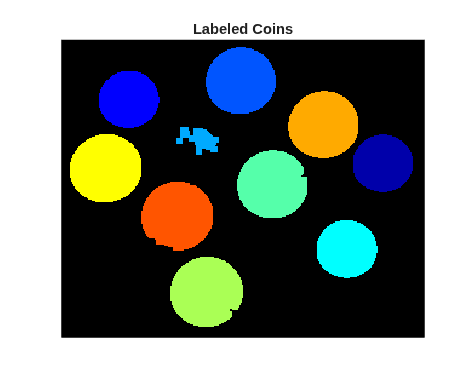


% Display labeled image
figure;
imshow(label2rgb(L, 'jet', 'k', 'shuffle'));
title('Labeled Coins');

## Exercise 6 - Short answers

Otsu separates the bright coins from the dark background, but dark patterns on the coins leave holes. imopen removes small bright specks and thin protrusions, imfill closes the holes inside the coins, and bwareaopen removes blobs smaller than 50 pixels. 10 coins are found. The largest is coin 4 with 2737 pixels. Coin 5 has only 440 pixels, which is far too small: for this coin the mask was not a closed ring, so imfill could not fill it and only a part is left. Filling before opening, or a lower threshold, would fix this. The coins in this image do not touch, so none are merged. Touching coins would become one label and would need a watershed step.